# Live Demo: Infectious disease spread in a neighborhood-level metapopulation model

### **6.336 Final Project**

**Suleeporn Yui Sujichantararat, Georgia Thomas, Jason Zhang     GROUP ID: DISEASE**

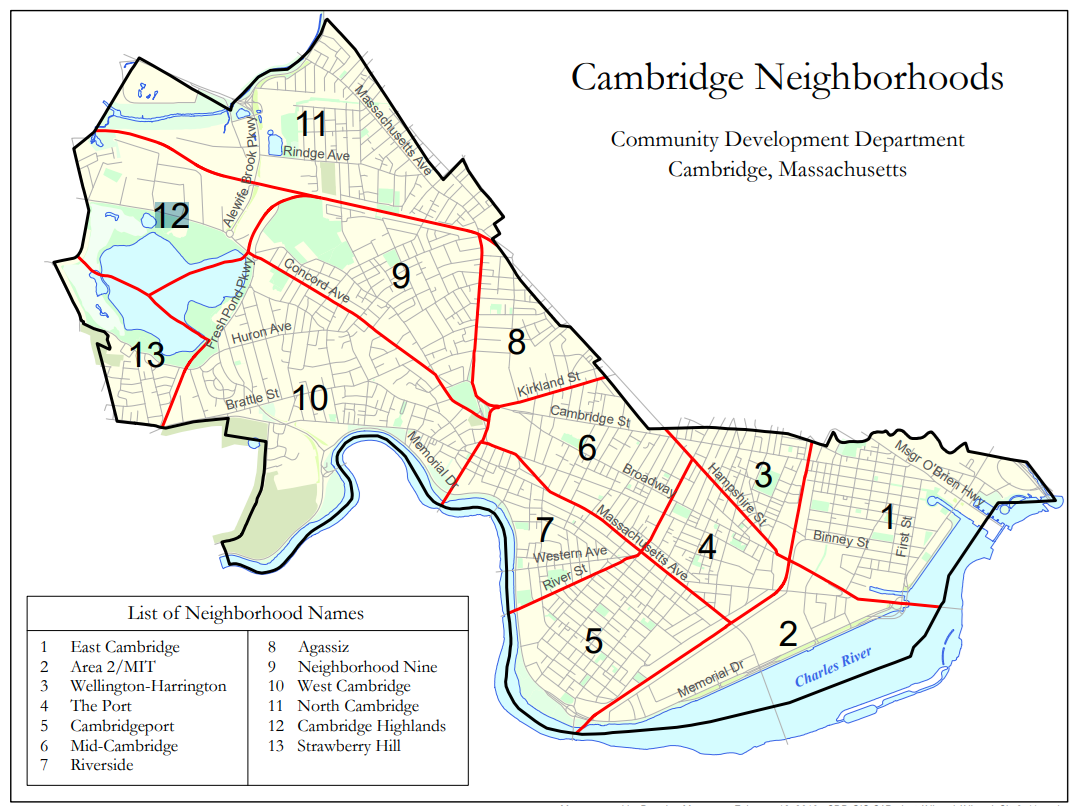

## **Simulation 1: Simple SEIR model, single neighborhood**

%% Setup
clc; close all; clear all;
addpath(genpath('C:\Users\Jason\Documents\Git\6336InfectiousDisease'))
cases = {'noTravel','noMeasures','cutOffMultiple'};
stateInitType = {'singleInfectedAll', 'MIToutbreak'};

%% Simulation and save results
% [ySim1, xSim1, pSim1] = SimSEIR(1, cases{1}, stateInitType{1}, dt);
% [ySim2, xSim2, pSim2] = SimSEIR(13, cases{2}, stateInitType{2}, dt); 

Timestep 1, Day 0.50, Newton Iter 1, nf 7.070737e+00, ndx 7.141807e+00
Timestep 1, Day 0.50, Newton Iter 2, nf 6.564081e-05, ndx 6.796167e-05
Timestep 1, Day 0.50, Newton Iter 3, nf 2.699656e-11, ndx 2.798168e-11
Timestep 2, Day 1.00, Newton Iter 1, nf 7.070737e+00, ndx 7.141807e+00
Timestep 2, Day 1.00, Newton Iter 2, nf 6.564081e-05, ndx 6.796167e-05
Timestep 2, Day 1.00, Newton Iter 3, nf 2.699656e-11, ndx 2.798168e-11
Timestep 3, Day 1.50, Newton Iter 1, nf 7.214374e+00, ndx 7.919834e+00
Timestep 3, Day 1.50, Newton Iter 2, nf 4.217489e-04, ndx 4.366258e-04
Timestep 3, Day 1.50, Newton Iter 3, nf 1.820231e-10, ndx 1.884273e-10
Timestep 4, Day 2.00, Newton Iter 1, nf 8.625428e+00, ndx 1.003274e+01
Timestep 4, Day 2.00, Newton Iter 2, nf 1.044645e-03, ndx 1.081344e-03
Timestep 4, Day 2.00, Newton Iter 3, nf 4.500526e-10, ndx 4.658601e-10
Timestep 5, Day 2.50, Newton Iter 1, nf 1.143832e+01, ndx 1.373196e+01
Timestep 5, Day 2.50, Newton Iter 2, nf 2.331247e-03, ndx 2.412625e-03
Timest

% [ySim3, xSim3, pSim3] = SimSEIR(13, cases{3}, stateInitType{2}, dt);
% save('Sim1.mat','ySim1','xSim1','pSim1')
% save('Sim2.mat','ySim2','xSim2','pSim2');
% save('Sim3.mat','ySim3','xSim3','pSim3');
load('Sim1.mat');
load('Sim2.mat');
load('Sim3.mat');
cambridge = readtable('Cambridge/cam.xlsx');

Plot the SEIR proportions (area) vs. time and the animated SEIR curves.

animationSpeed = 0.5;

f1 = figure(1)

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


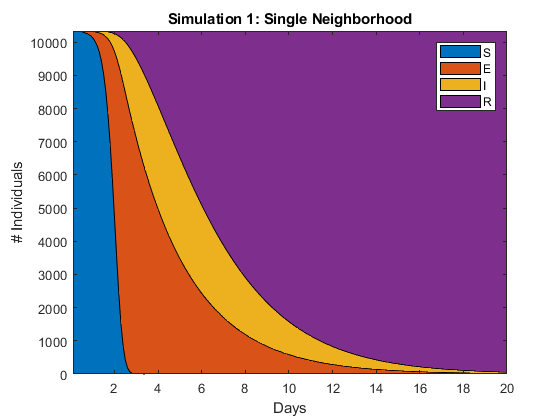

plotSEIRProp(f1,ySim1,xSim1,dt,'Simulation 1: Single Neighborhood');
set(f1,'position',[290   336   560   420]);


f2 = figure(2)

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


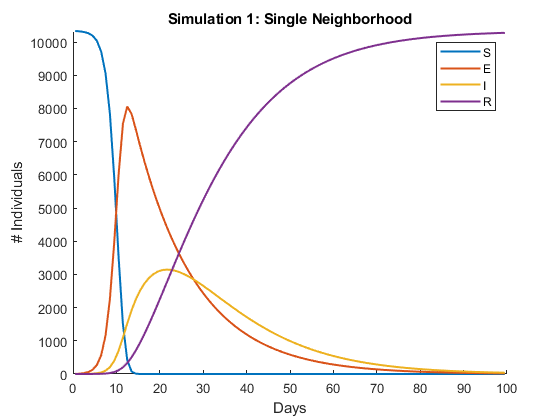

animateSEIR(f2,ySim1,animationSpeed,'Simulation 1: Single Neighborhood');

## Simulation 2 & 3: SEIR metapopulation (multiple neighborhoods) model, with and without measures

- 13 neighborhoods, single infected person in Neighborhood 2 (MIT)

- Simulation 2 is without measures; Simulation 3 is with measures

f3 = figure(3);
geovisSEIR(f3,xSim2,dt,pSim2,1,false,'Sim 2 Without Measures',cambridge);

f4 = figure(4);
geovisSEIR(f4,xSim2,dt,pSim2,1,true,'Sim 2 (No Measures)',cambridge);
set(f4, 'position', [379   303   560   420])
f5 = figure(5);
geovisSEIR(f5,xSim3,dt,pSim3,1,true,'Sim 3 (Measures)',cambridge);
set(f5, 'position', [945   303   560   420])

f6 = figure(6);
geovisSEIR(f6,xSim3,dt,pSim3,1,false,'Sim 3 With Measures',cambridge);

f7 = figure(7);
plotSEIRProp(f7,ySim2,xSim2,dt);
set(f7,'position',[17    82   595   905]);
sgtitle('Simulation 2: No Measures, Neighborhood Breakdown');
f8 = figure(8);
plotSEIRProp(f8,ySim3,xSim3,dt);
set(f8,'position',[618    82   595   905]);
sgtitle('Simulation 3: Measures, Neighborhood Breakdown');
f9 = figure(9);
compareSEIR(f9,ySim2,ySim3,dt);
xlabel('Time (days)')
ylabel('# Individuals');
title('Measures (solid). vs. No Measures (dotted)')
set(gcf,'position',[1217 560 560 420]);